%robot parameters
r = 1.5;
L=3;
R=3.5;

params = [r, L, R];

%variables
x0 = [0.5, 0, 10];
xf = [0.5, 0, 10];
t = linspace(0,1,2)

t =      0     1


n = length(t);
T = t(end);

%xplan
x = x_plan(x0,xf,t)

x =     0.5000    0.5000
         0         0
    0.1745    0.1745


% x = x_plan(x(:,42)', xf, t)

%inv kin
[q,q_fin,leg_config] = inv_kin(x, t, params);

i=1

i = 1

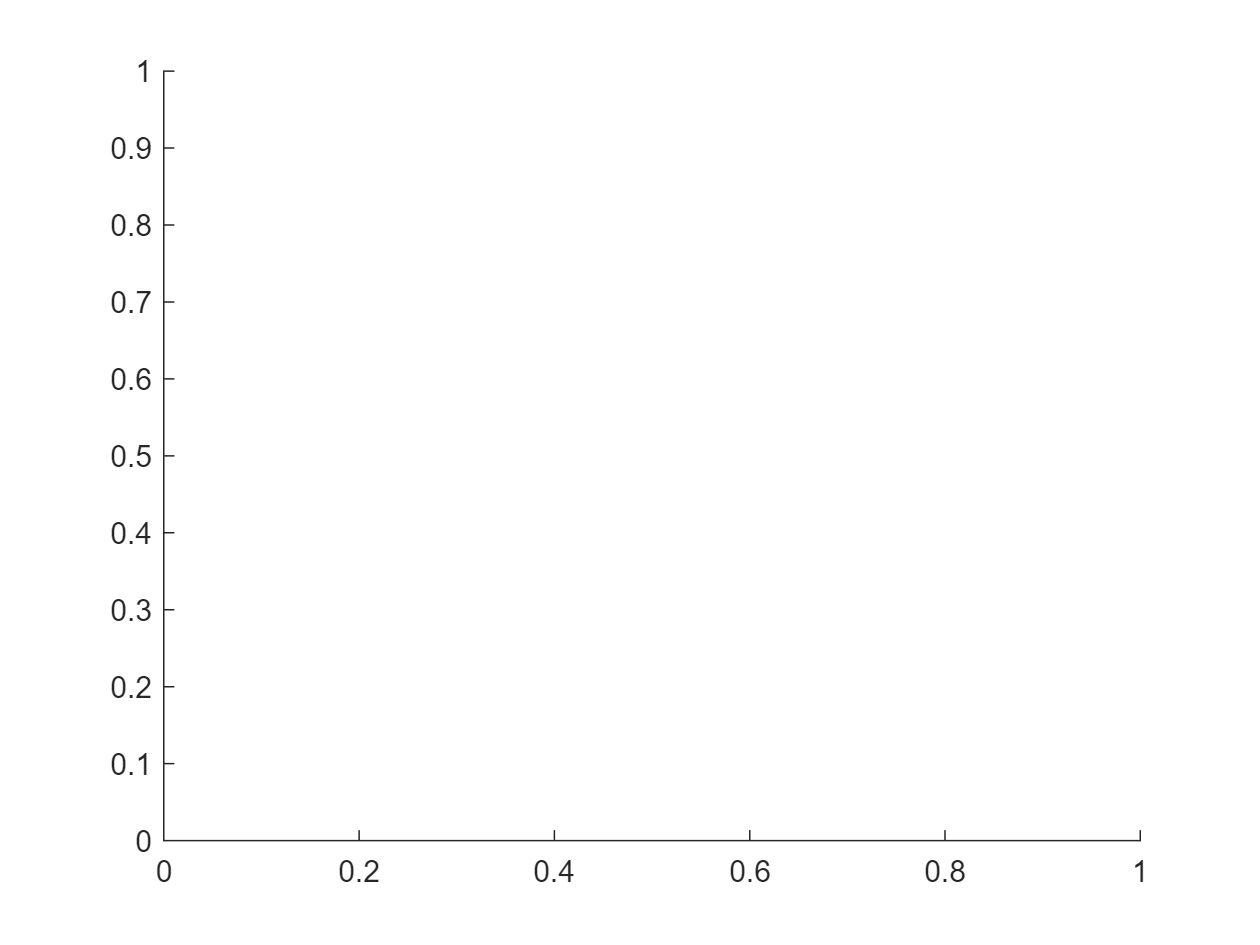

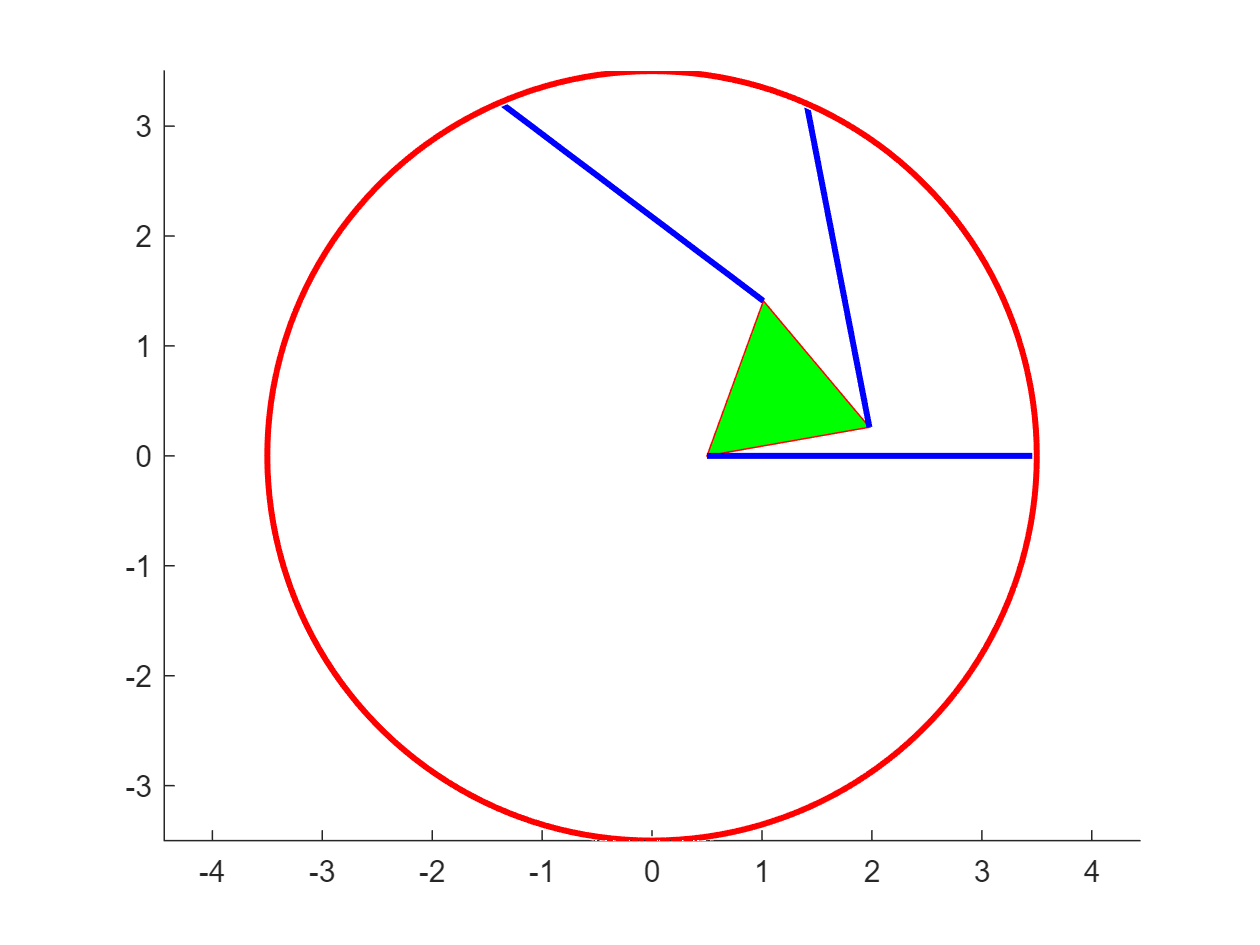

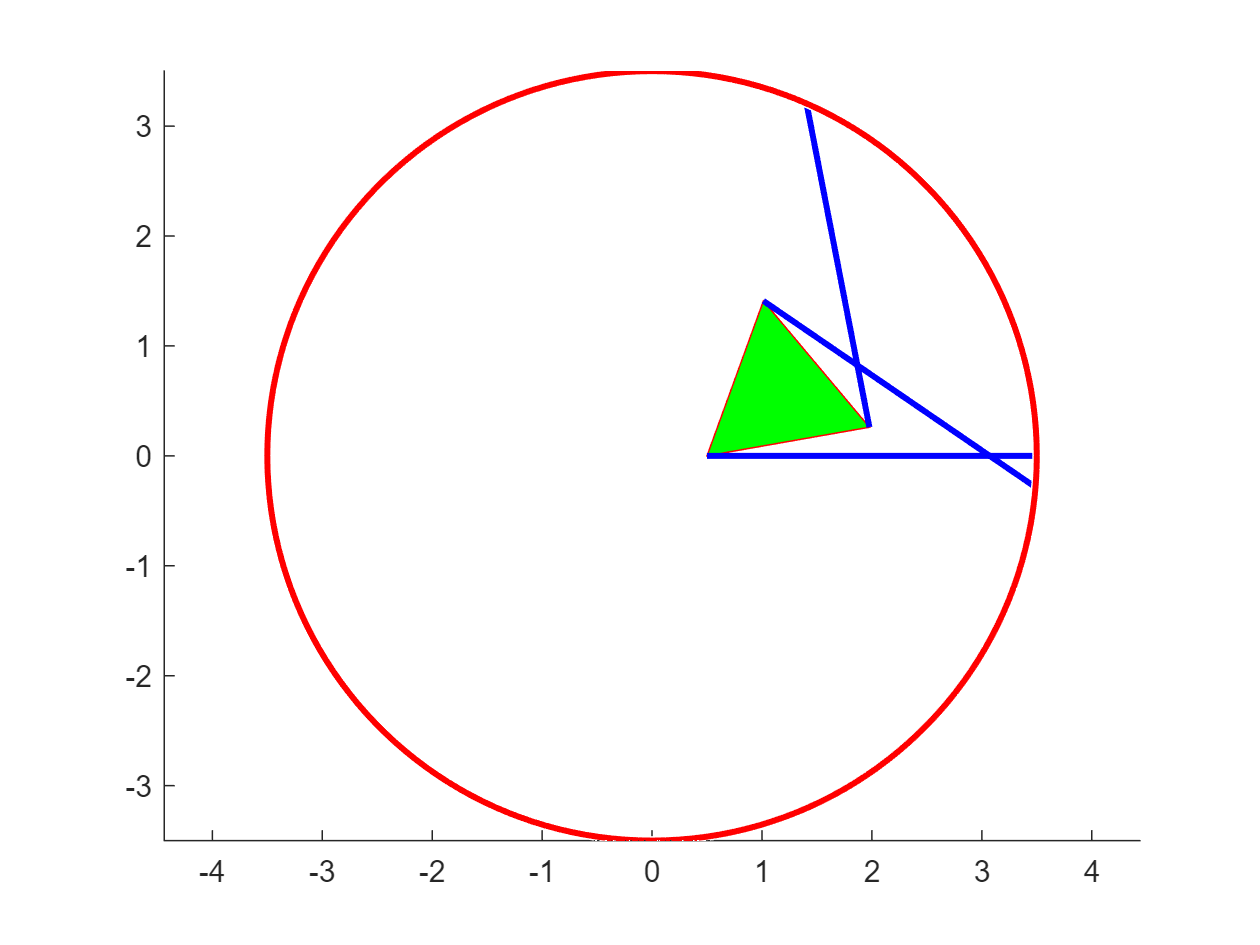

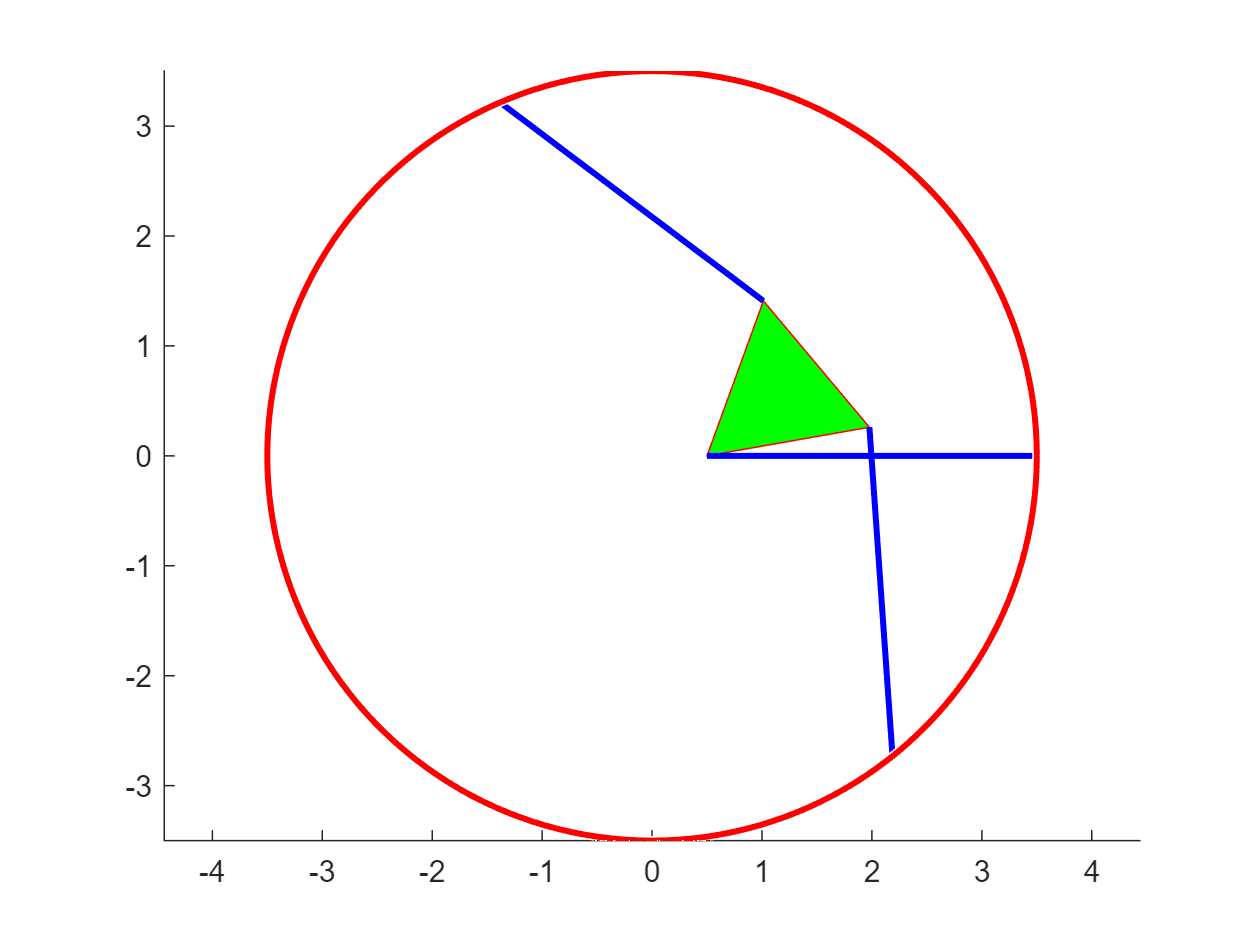

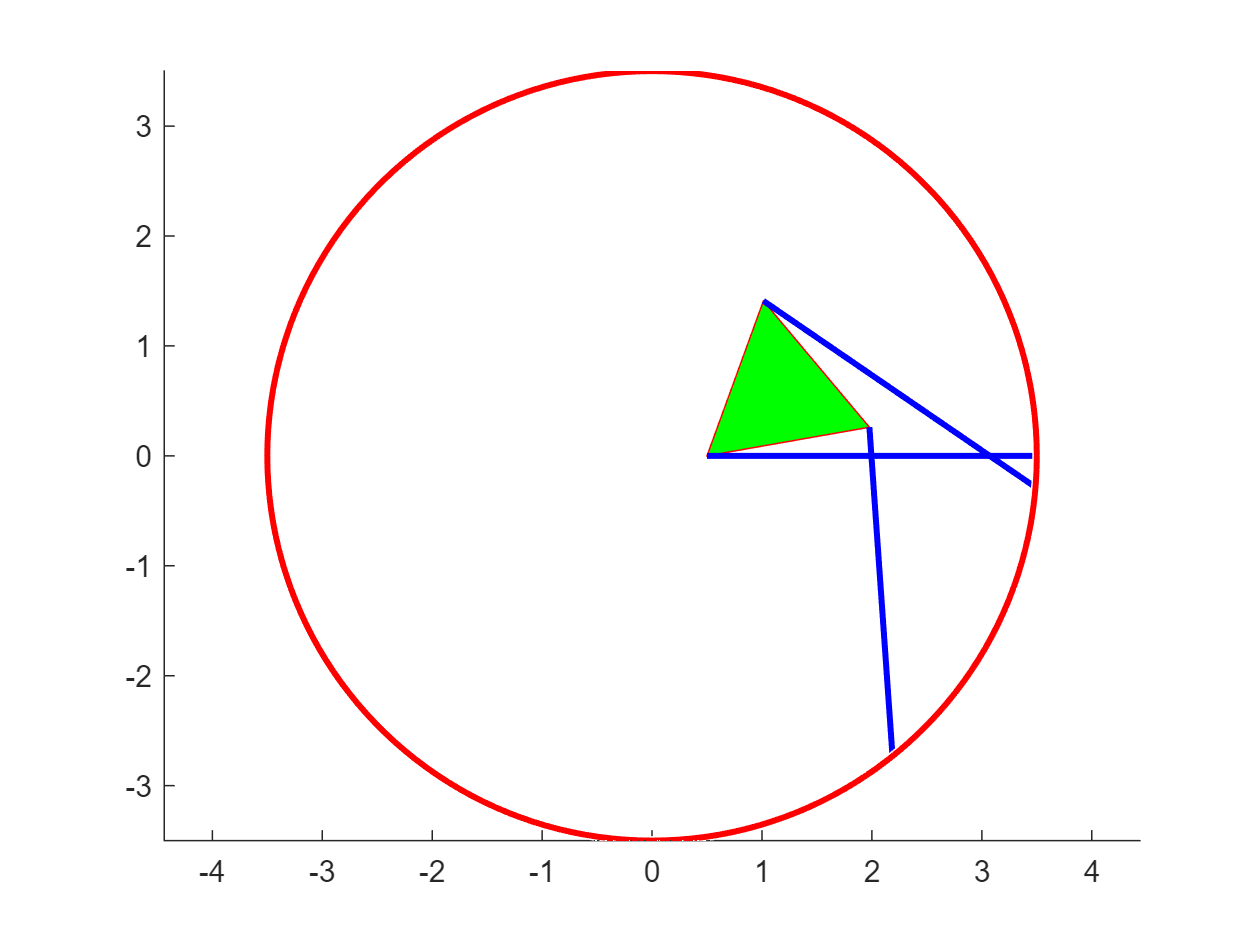

for w=1:8
    hold off
    x1 = x(1,i); x2 = x(1,i)+r*cos(x(3,i)); x3 = x(1,i)+r*cos(x(3,i)+deg2rad(60));
    y1 = x(2,i); y2 = x(2,i)+r*sin(x(3,i)); y3 = x(2,i)+r*sin(x(3,i)+deg2rad(60));

    figure
    patch([x1 x2 x3], [y1 y2 y3], 'green', 'edgecolor', 'red')
    hold on
    plot(leg_config(1,:,1,w),leg_config(2,:,1,w), 'blue', 'linewidth', 2)
    plot(leg_config(1,:,2,w),leg_config(2,:,2,w), 'blue', 'linewidth', 2)
    plot(leg_config(1,:,3,w),leg_config(2,:,3,w), 'blue', 'linewidth', 2)
    
    axis equal
    hold off

    viscircles([0,0],R);
end

i=2

i = 2

for w=1:8
    hold off
    x1 = x(1,i); x2 = x(1,i)+r*cos(x(3,i)); x3 = x(1,i)+r*cos(x(3,i)+deg2rad(60));
    y1 = x(2,i); y2 = x(2,i)+r*sin(x(3,i)); y3 = x(2,i)+r*sin(x(3,i)+deg2rad(60));

    figure
    patch([x1 x2 x3], [y1 y2 y3], 'green', 'edgecolor', 'red')
    hold on
    plot(leg_config(1,:,1,w),leg_config(2,:,1,w), 'blue', 'linewidth', 2)
    plot(leg_config(1,:,2,w),leg_config(2,:,2,w), 'blue', 'linewidth', 2)
    plot(leg_config(1,:,3,w),leg_config(2,:,3,w), 'blue', 'linewidth', 2)
    axis equal
    hold off

    viscircles([0,0],R);
end